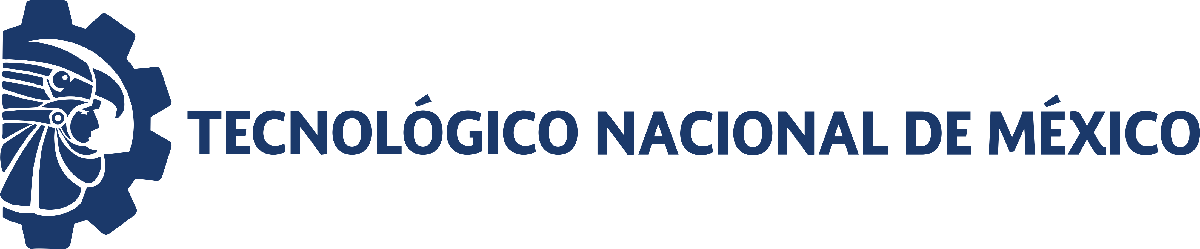                                 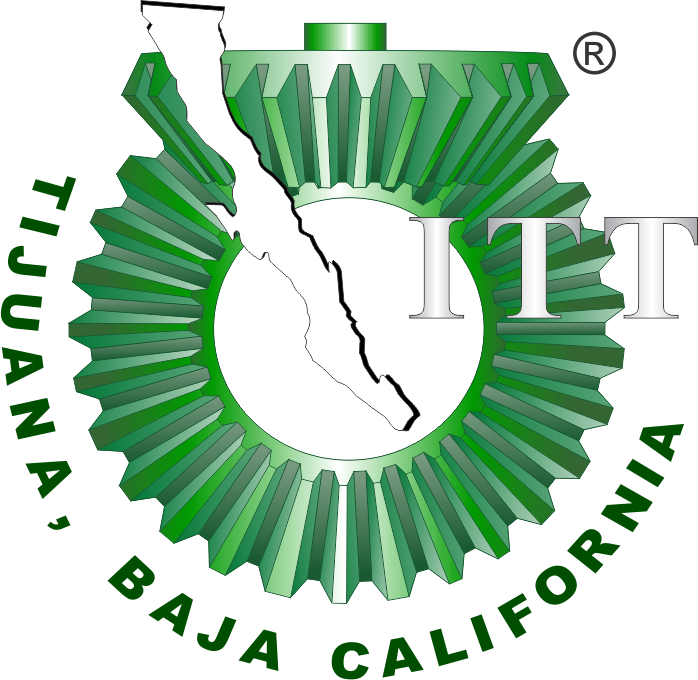

# Práctica dos: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

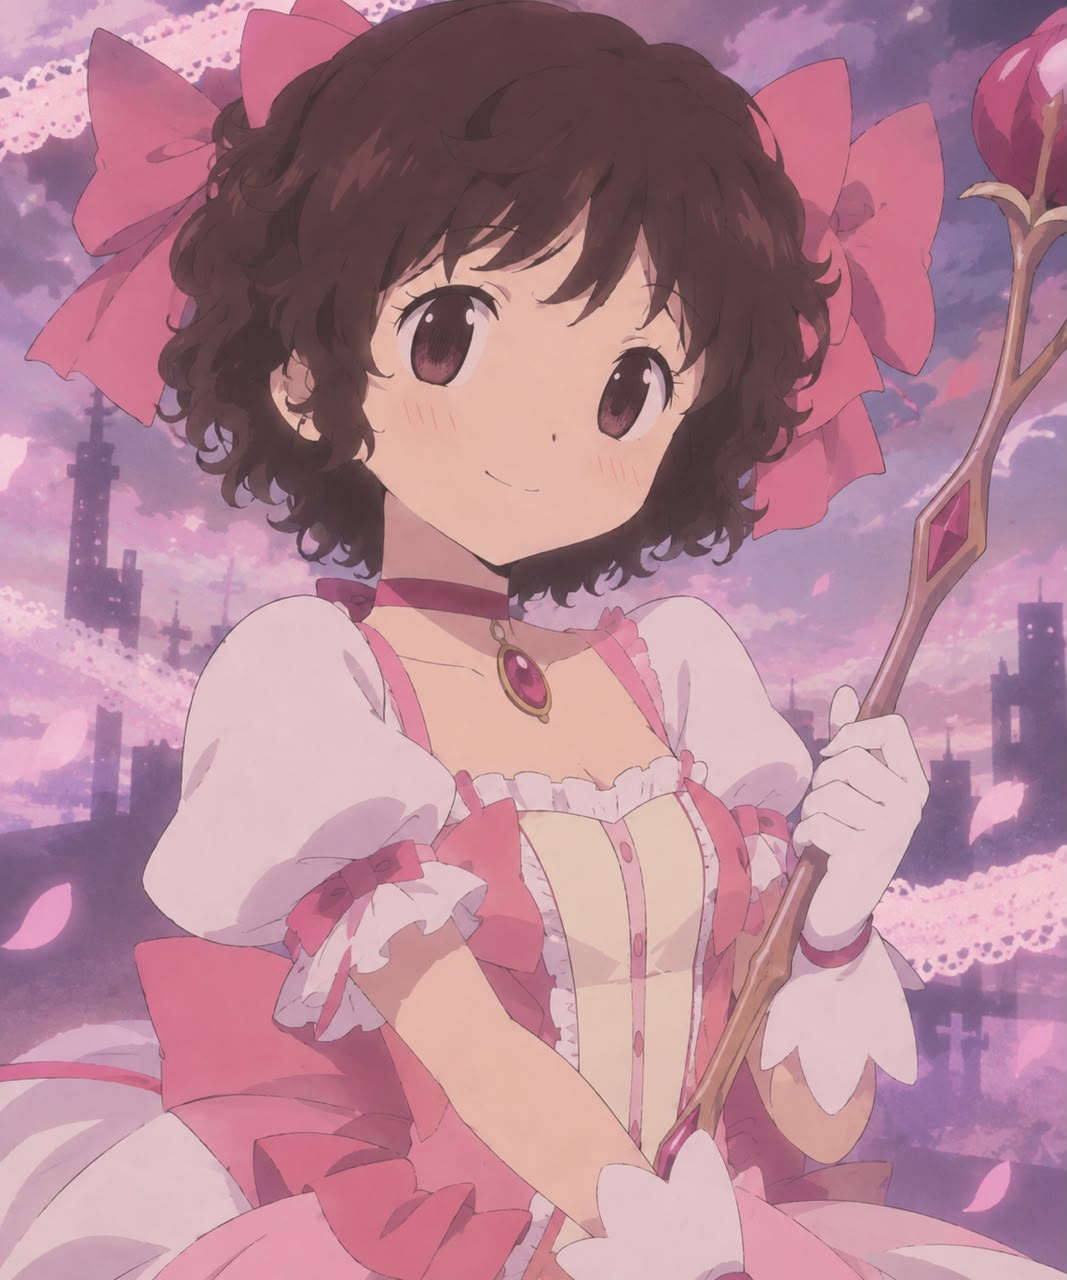

Nombre del alumno: **Nicole Arredondo Arevalo**

Número de control: 23212179

Correo institucional: L23212179**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema2')
parameters.StopTime = '15'

parameters = struct with fields:
    StopTime: '15'


parameters.Solver = 'ode15s'

parameters = struct with fields:
    StopTime: '15'
      Solver: 'ode15s'


parameters.MaxStep = '1e-3'

parameters = struct with fields:
    StopTime: '15'
      Solver: 'ode15s'
     MaxStep: '1e-3'


x=sim('sistema2',parameters)

x =   Simulink.SimulationOutput:

                   PIDL: [18088x1 double] 
                  PIDLH: [18088x1 double] 
                     Pa: [151x1 double] 
                    PpH: [18088x1 double] 
                    PpL: [18088x1 double] 
                    PpN: [18088x1 double] 
                      t: [18088x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t_data = (0:0.1:15)';
t = (0:0.1:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');
writematrix(Pa,'signal.xlsx')
% set_param('sistema/Vs(t): CE/Vs','VectorFormat','1-D array');

## Respuestas: Hipotenso, Normotenso e Hipertenso

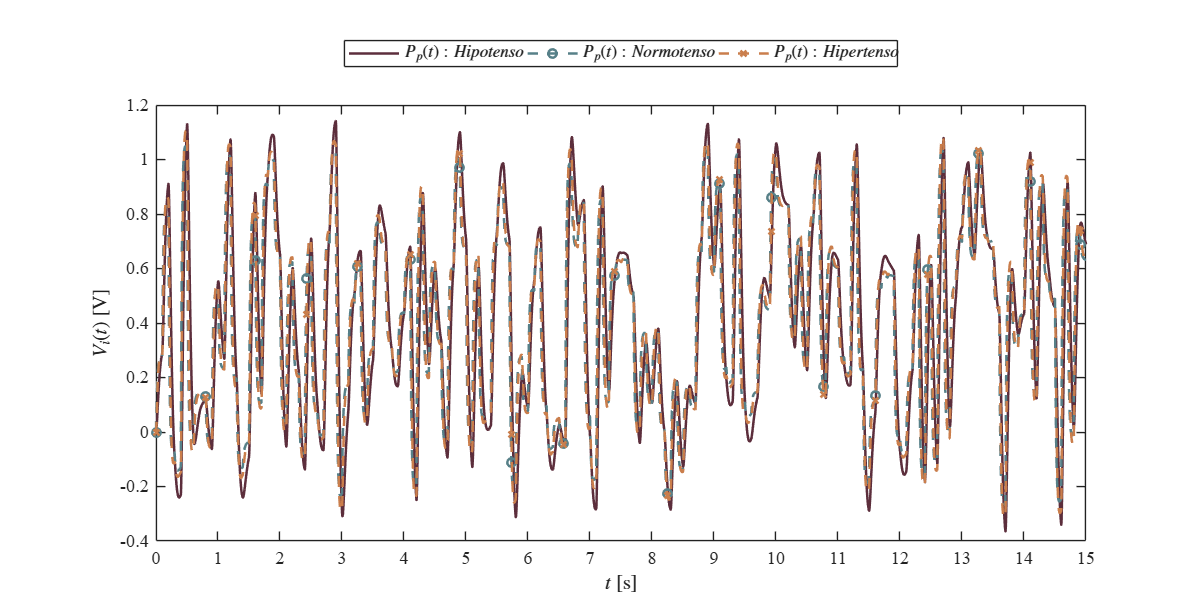

plotsignals(x.t,x.PpL,x.PpN,x.PpH,'Individuos')

## Respuestas: Normotenso, Hipotenso y Controlador

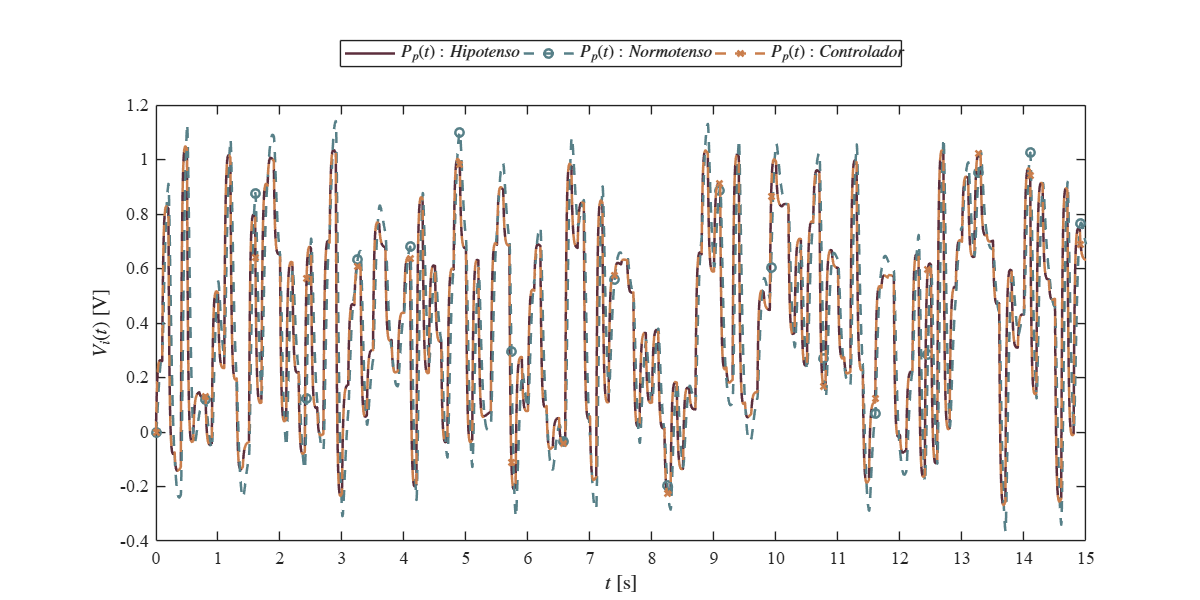

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuestas Normotenso, Hipertenso y Controlador

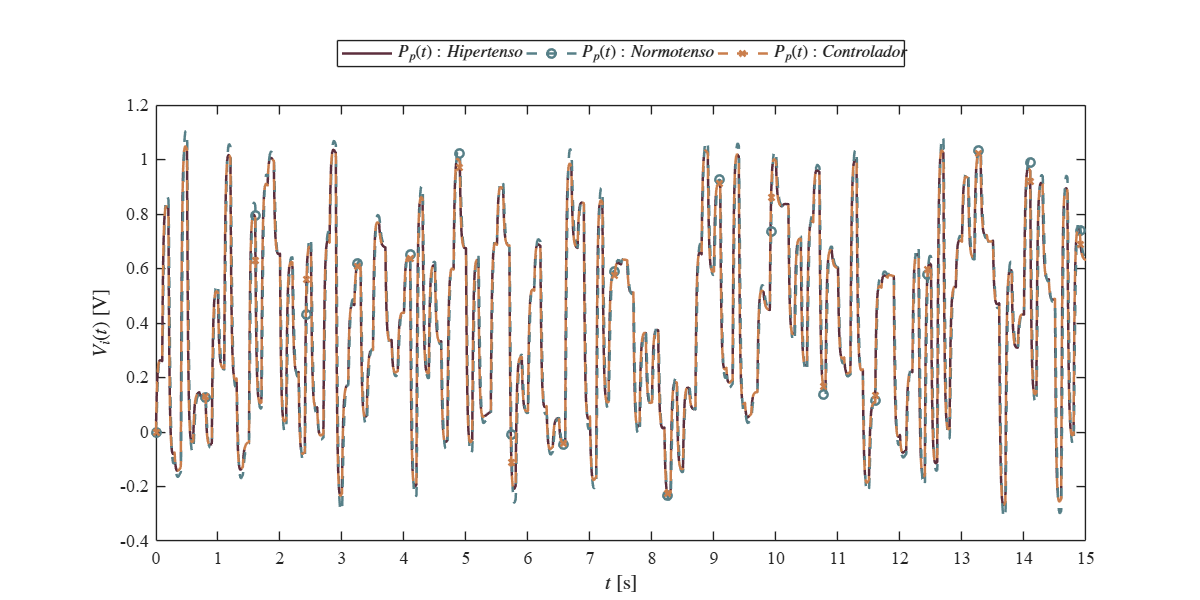

plotsignals(x.t,x.PpN,x.PpH,x.PIDLH,'Hipertenso')

## **Funcion: Respuestas de la simulacion **

function plotsignals(t,PpN,PpL,PpH,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,10,5])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [92, 46, 60]/255;
    clr2 = [87, 128, 136]/255;
    clr3 = [202, 126, 76]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,PpN,'-',t,PpL,'--o',t,PpH,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));


    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    if signal == "Individuos"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
        L = legend('$P_p(t): Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Hipertenso$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    elseif signal == "Hipotenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
        L = legend('$P_p(t):Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Controlador$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    elseif signal == "Hipertenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
        L = legend('$P_p(t):Hipertenso$','$P_p(t):Normotenso$','$P_p(t): Controlador$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    end

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')

end